% Risk Analysis in Commercial Logistics using DEMATEL in Manzanillo port
% Date: 11 March 2025
% Author:  Enrique Cárdenas Sánchez

% Inspirado en Barghi, B. (2020). Qualitative and quantitative project risk assessment using a hybrid PMBOK model developed under uncertainty conditions. Heliyon, 6(1).

%% Step 1: Definition of Risks
risks = {'Delays', 'Accidents', 'Weather', 'Road Conditions', 'Traffic'};
n_risks = length(risks);

%% Step 2: Creation of the Direct Relation Matrix (A)
% Scale: 0 (no influence) to 1 (very high influence)
% Matrix based on expert judgement (hypothetical example)
A = [0, 0.5, 0.3, 0.2, 0.4;    % Delays
     0.3, 0, 0.1, 0.4, 0.2;    % Accidents
     0.4, 0.2, 0, 0.3, 0.3;    % Weather
     0.2, 0.5, 0.3, 0, 0.2;    % Road Conditions
     0.5, 0.3, 0.2, 0.4, 0];   % Traffic

disp('Direct Relation Matrix (A):');

Direct Relation Matrix (A):


disp(A);

         0    0.5000    0.3000    0.2000    0.4000
    0.3000         0    0.1000    0.4000    0.2000
    0.4000    0.2000         0    0.3000    0.3000
    0.2000    0.5000    0.3000         0    0.2000
    0.5000    0.3000    0.2000    0.4000         0




%% Step 3: Normalisation of the Relation Matrix
% Normalisation by dividing by the maximum row sum
row_sums = sum(A, 2);
max_sum = max(row_sums);
A_normalised = A / max_sum;

disp('Normalised Relation Matrix (A_normalised):');

Normalised Relation Matrix (A_normalised):


disp(A_normalised);

         0    0.3571    0.2143    0.1429    0.2857
    0.2143         0    0.0714    0.2857    0.1429
    0.2857    0.1429         0    0.2143    0.2143
    0.1429    0.3571    0.2143         0    0.1429
    0.3571    0.2143    0.1429    0.2857         0




%% Step 4: Calculation of the Total Relation Matrix (T)
% T = (I - A_normalised)^(-1) - I
I = eye(n_risks); % Identity matrix
T = inv(I - A_normalised) - I;

disp('Total Relation Matrix (T):');

Total Relation Matrix (T):


disp(T);

    1.5874    2.0304    1.2759    1.6632    1.5403
    1.3625    1.3509    0.9159    1.3823    1.1189
    1.6523    1.7231    1.0047    1.5491    1.3691
    1.4781    1.7824    1.1187    1.3166    1.2476
    1.8744    1.9843    1.2580    1.7734    1.3419




%% Step 5: Calculation of R and J
% R: Total influence exerted (row sums)
R = sum(T, 2);

% J: Total influence received (column sums)
J = sum(T, 1)';

disp('Total Influence Exerted (R):');

Total Influence Exerted (R):


disp(R);

    8.0973
    6.1305
    7.2983
    6.9433
    8.2320



disp('Total Influence Received (J):');

Total Influence Received (J):


disp(J);

    7.9546
    8.8711
    5.5732
    7.6846
    6.6178




%% Step 6: Calculation of R+J and R-J
R_plus_J = R + J; % Total importance
R_minus_J = R - J; % Net impact

disp('R+J (Total Importance):');

R+J (Total Importance):


disp(R_plus_J);

   16.0519
   15.0016
   12.8714
   14.6279
   14.8498



disp('R-J (Net Impact):');

R-J (Net Impact):


disp(R_minus_J);

    0.1427
   -2.7406
    1.7251
   -0.7413
    1.6142




%% Step 7: Prioritisation of Risks
% Sort risks by R+J (descending order)
[~, order] = sort(R_plus_J, 'descend');
prioritised_risks = risks(order);
R_plus_J_prioritised = R_plus_J(order);
R_minus_J_prioritised = R_minus_J(order);

disp('Risks Prioritised by R+J:');

Risks Prioritised by R+J:


for i = 1:n_risks
    fprintf('%d. %s - R+J: %.4f, R-J: %.4f\n', i, prioritised_risks{i}, ...
            R_plus_J_prioritised(i), R_minus_J_prioritised(i));
end

1. Delays - R+J: 16.0519, R-J: 0.1427
2. Accidents - R+J: 15.0016, R-J: -2.7406
3. Traffic - R+J: 14.8498, R-J: 1.6142
4. Road Conditions - R+J: 14.6279, R-J: -0.7413
5. Weather - R+J: 12.8714, R-J: 1.7251


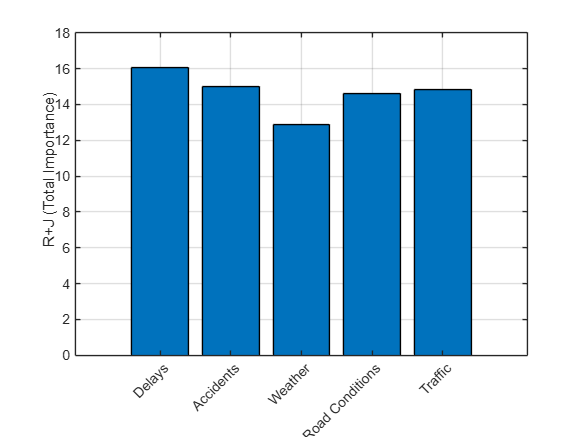


%% Visualisation
% Bar chart for R+J
figure;
bar(R_plus_J);
set(gca, 'XTick', 1:n_risks, 'XTickLabel', risks, 'XTickLabelRotation', 45);
ylabel('R+J (Total Importance)');
title('Risk Prioritisation in Commercial Logistics (DEMATEL)');
grid on;

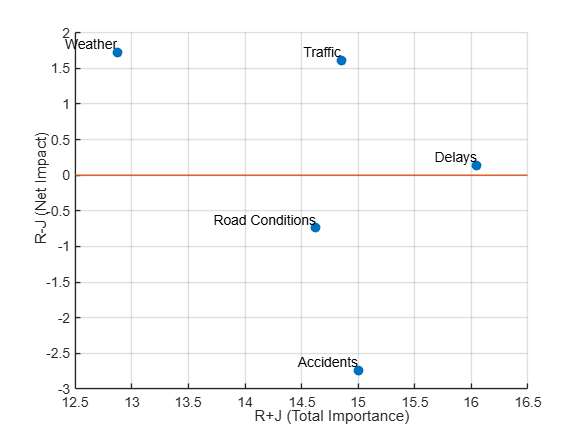


% Scatter plot for R-J vs R+J
figure;
scatter(R_plus_J, R_minus_J, 50, 'filled');
for i = 1:n_risks
    text(R_plus_J(i), R_minus_J(i), risks{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
xlabel('R+J (Total Importance)');
ylabel('R-J (Net Impact)');
title('DEMATEL Analysis: Importance vs Net Impact');
grid on;
refline(0, 0); % Horizontal line at y=0

**Interpretation**

- **Definition of Risks**: The five risks (Delays, Accidents, Weather, Road Conditions, Traffic) are defined.

- **Direct Relation Matrix (A)**: 

- A 5x5 matrix is created with values from 0 to 1, representing the direct influence of one risk on another. These are hypothetical values for demonstration.

- **Normalisation**: 

- The matrix A is normalised by dividing each element by the maximum row sum, ensuring all values are between 0 and 1.

- **Total Relation Matrix (T)**: 

- Calculated using the formula T = (I - A_normalised)^(-1) - I, accounting for both direct and indirect influences.

- **Calculation of R and J**: 

- R (total influence exerted) is the sum of rows in T.

- J (total influence received) is the sum of columns in T.

- **Calculation of R+J and R-J**: 

- R+J represents the total importance of each risk.

- R-J indicates the net impact (positive means a risk exerts more influence; negative means it receives more).

- **Prioritisation**: 

- Risks are sorted by R+J in descending order to identify the most critical ones.

- **Visualisation**: 

- A bar chart displays R+J for each risk.

- A scatter plot shows R+J vs R-J, with a reference line at y=0 to distinguish emitters from receivers.